## generate matrix

rng(36,'twister');

LENGTH = 40;
%core = ones(LENGTH/2,LENGTH/2);
%kn = ones(2,2);
%area = kron(core,kn);


## generate initial position

ROBOT_NUM = 1;
init_pos = unifrnd(1,LENGTH+1,[ROBOT_NUM,2])

init_pos =    30.1403   25.0646


%init_grid = round(init_pos)

a = 8; b = 10;
kn = ones(a,b);
core = zeros(LENGTH/a,LENGTH/b);
core(ceil(init_pos(1)/a),ceil(init_pos(2)/b)) = 1;
area = kron(core,kn);
size(area)

ans =     40    40


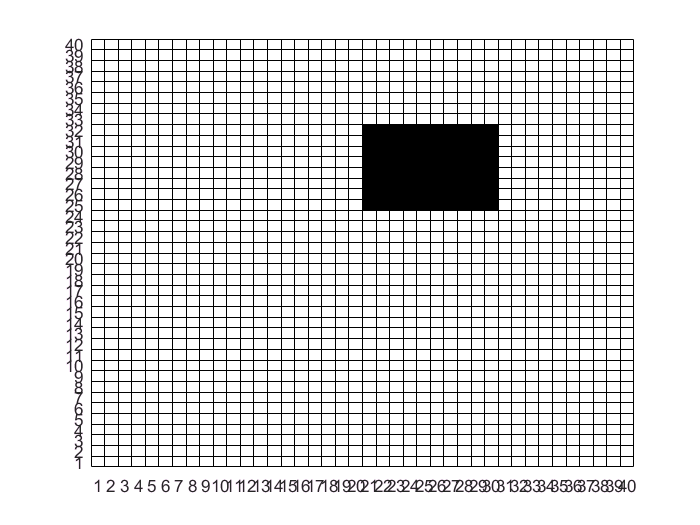


B = area;
B(end+1,end+1) = 0;
colormap([1 1 1;0 0 0]);  % color
pcolor(0.5:size(area,2)+0.5,0.5:size(area,1)+0.5,B); % grid color

set(gca,'XTick',1:size(area,2),'YTIck',1:size(area,1));


%robot_pos = init_pos + [randi([-a,a],1,1), randi([-b,b],1,1)]


## Test Connectivity Probability function

% gaosi
x_roi = (1:a) + (ceil(init_pos(1)/a)-1)*a

x_roi =     25    26    27    28    29    30    31    32


y_roi = (1:b) + (ceil(init_pos(2)/b)-1)*b

y_roi =     21    22    23    24    25    26    27    28    29    30


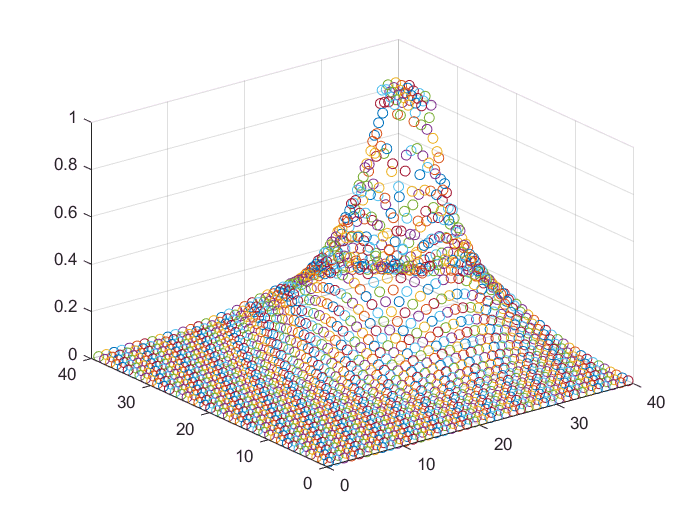

sigmx = sqrt(sum((x_roi - init_pos(1)).^2));
sigmy = sqrt(sum((y_roi - init_pos(2)).^2));
ux = sum(x_roi - init_pos(1))/a;
uy = sum(y_roi - init_pos(2))/b;

h = @(v) exp(-sum(((v-init_pos-[ux,uy])./[sigmx,sigmy]).^2)/2);

% charge like field
um = zeros(1,2);
um(1) = max(x_roi-init_pos(1));
um(2) = max(y_roi-init_pos(2));

q1 = 2;
q2 = 1.5;
%um = [0,20];
%f=@(v) q1/(v*v')+q2/((v-um)*(v-um)');
f=@(v) q1/((v-init_pos)*(v-init_pos)')^0.4+q2/(((v-init_pos)-um)*((v-init_pos)-um)')^0.4;

% combine two possibility function
z1 = zeros(LENGTH,LENGTH);
z2 = zeros(LENGTH,LENGTH);
the = f(um*q2/(q1+q2)+init_pos);
for i = 1:LENGTH
    for j = 1:LENGTH
        z1 = h([i,j]);
        z2 = f([i,j]);
        if z2 > the
            z2 = 1;
        else
            z2 = z2 / the;
        end
        z = z1*z2;
        if z > 0.75
            z = 1;
        else
            z = z^(0.25/z);
        end
        scatter3(i,j,z);
        hold on
    end
end



%% 